clear all

#  EXTRAER ARCHIVOS

NxyzTABLE = readtable('Nxyz.xlsx','ReadRowNames',true);

NxyzTABLE.Properties.VariableNames{1} = 'X';
NxyzTABLE.Properties.VariableNames{2} = 'Y';
NxyzTABLE.Properties.VariableNames{3} = 'Z';


num_col = length(NxyzTABLE.Properties.RowNames);


%       CREAMOS TABLAS CON DATOS
xyz = NxyzTABLE{1:num_col,{'X','Y','Z'}}; %tabla con xyz
x_o = NxyzTABLE{1:num_col,{'X'}}; %separamos datos para graficar puntos
y_o = NxyzTABLE{1:num_col,{'Y'}};
z_o = NxyzTABLE{1:num_col,{'Z'}};


# DATOS PISTA

logitudPista=3020;
anchuraPista=30;
%   DATOS SUPERFICIE DE TRANSICION
FranjaAnchura=150;
FranjaLongitud=60;
pendienteTransicion=0.143;
altura=45;
%  DATOS DESPEGUE
LogitudBordeInteriorDespegue=180;
DivergenciaDespegue=0.125;
logitudTotal=6480;
pendienteDespegue=0.02;

logitudTotal2=8520;

%   DATOS APROX
LogitudBordeInteriorAprox=300;
DivergenciaAprox=0.15;
LongitudPrimeraSeccion=3000;
pendienteAproximacion=0.02;


LongitudSegundaSeccion=3600;
pendienteAproximacion2=0.025;

LongitudTerceraSeccion=8600;


## Creamos figura pista

XXpista = [0,0,0,0,logitudPista,logitudPista,logitudPista,logitudPista]';
YYpista = [anchuraPista/2,anchuraPista/2,-anchuraPista/2,-anchuraPista/2,anchuraPista/2,anchuraPista/2,-anchuraPista/2,-anchuraPista/2]';
ZZpista = [0,1,0,1,0,1,0,1]';
Figurapista = alphaShape(XXpista,YYpista,ZZpista); %cramos la figura


## CREAMOS SUPERFICIE DE TRANSICION

% estas son las aristas de nuestro volumen
 XXtrans = [-FranjaLongitud,-FranjaLongitud,logitudPista+FranjaLongitud,logitudPista+FranjaLongitud,...
    -(altura/pendienteTransicion+FranjaLongitud),-(altura/pendienteTransicion+FranjaLongitud),-FranjaLongitud,...
    -FranjaLongitud,logitudPista+FranjaLongitud,logitudPista+FranjaLongitud,logitudPista+FranjaLongitud+altura/pendienteTransicion,...
    logitudPista+FranjaLongitud+altura/pendienteTransicion]';
YYtrans = [FranjaAnchura,-FranjaAnchura,-FranjaAnchura,+FranjaAnchura,...
    FranjaAnchura+DivergenciaAprox*(altura/pendienteTransicion),-(FranjaAnchura+DivergenciaAprox*(altura/pendienteTransicion)),...
    altura/pendienteTransicion+FranjaAnchura,-(altura/pendienteTransicion+FranjaAnchura),...
    altura/pendienteTransicion+FranjaAnchura,-(altura/pendienteTransicion+FranjaAnchura),...
    FranjaAnchura+DivergenciaAprox*(altura/pendienteTransicion),...
    -(FranjaAnchura+DivergenciaAprox*(altura/pendienteTransicion))]';
ZZtrans = [0,0,0,0,altura,altura,altura,altura,altura,altura,altura,altura]';

Figuratrans = alphaShape(XXtrans,YYtrans,ZZtrans); %cramos la figura

%TRANS 2
XXtrans2 = [-FranjaLongitud,-FranjaLongitud,logitudPista+FranjaLongitud,logitudPista+FranjaLongitud,...
    -FranjaLongitud,-FranjaLongitud,logitudPista+FranjaLongitud,logitudPista+FranjaLongitud]';
YYtrans2 = [FranjaAnchura,-FranjaAnchura,-FranjaAnchura,+FranjaAnchura,...
    altura/pendienteTransicion+FranjaAnchura,-(altura/pendienteTransicion+FranjaAnchura),...
    altura/pendienteTransicion+FranjaAnchura,-(altura/pendienteTransicion+FranjaAnchura)]';
ZZtrans2 = [0,0,0,0,altura,altura,altura,altura]';

Figuratrans2 = alphaShape(XXtrans2,YYtrans2,ZZtrans2);

%TRANS 3 
XXtrans3 = [-FranjaLongitud,-FranjaLongitud,...
    -(altura/pendienteTransicion+FranjaLongitud),-(altura/pendienteTransicion+FranjaLongitud),...
    -(altura/pendienteTransicion+FranjaLongitud),-(altura/pendienteTransicion+FranjaLongitud),]';
YYtrans3 = [FranjaAnchura,-FranjaAnchura,...
    FranjaAnchura+DivergenciaAprox*(altura/pendienteTransicion),-(FranjaAnchura+DivergenciaAprox*(altura/pendienteTransicion)),...
    FranjaAnchura+DivergenciaAprox*(altura/pendienteTransicion),-(FranjaAnchura+DivergenciaAprox*(altura/pendienteTransicion))]';
ZZtrans3= [0,0,altura,altura,0,0]';

Figuratrans3 = alphaShape(XXtrans3,YYtrans3,ZZtrans3);

%TRANS 4
XXtrans4 = [logitudPista+FranjaLongitud,logitudPista+FranjaLongitud,...
    logitudPista+FranjaLongitud+altura/pendienteTransicion,logitudPista+FranjaLongitud+altura/pendienteTransicion...
    logitudPista+FranjaLongitud+altura/pendienteTransicion,logitudPista+FranjaLongitud+altura/pendienteTransicion]';
YYtrans4 = [FranjaAnchura,-FranjaAnchura,...
    FranjaAnchura+DivergenciaDespegue*(altura/pendienteTransicion),-(FranjaAnchura+DivergenciaDespegue*(altura/pendienteTransicion)),...
    FranjaAnchura+DivergenciaDespegue*(altura/pendienteTransicion),-(FranjaAnchura+DivergenciaDespegue*(altura/pendienteTransicion)),]';
ZZtrans4 = [0,0,altura,altura,0,0]';

Figuratrans4 = alphaShape(XXtrans4,YYtrans4,ZZtrans4);




#### MIRAR SI ESTA EN SUPERCICIE TRANS i TRANS 2, TRANS 3

EstaEnTRANS = inShape(Figuratrans,xyz); %mirar si es dentro o fuera (figura,puntos)
EstaEnTRANS2 = inShape(Figuratrans2,xyz);
EstaEnTRANS3 = inShape(Figuratrans3,xyz);
EstaEnTRANS4 = inShape(Figuratrans4,xyz);



## CREAMOS SUPERFICIE DE APROXIMACION

% estas son las aristas de nuestro volumen
XXaprox = [-(LongitudPrimeraSeccion+FranjaLongitud),-(LongitudPrimeraSeccion+FranjaLongitud),-FranjaLongitud,-FranjaLongitud,...
    -(LongitudPrimeraSeccion+FranjaLongitud),-(LongitudPrimeraSeccion+FranjaLongitud)]';
YYaprox = [FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion,-(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion),...
    -FranjaAnchura,FranjaAnchura,FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion,...
    -(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion)]';
ZZaprox = [0,0,0,0,pendienteAproximacion*LongitudPrimeraSeccion,pendienteAproximacion*LongitudPrimeraSeccion]';

FiguraAprox = alphaShape(XXaprox,YYaprox,ZZaprox); %cramos la figura


APPROX 2

XXaprox2 = [-(LongitudPrimeraSeccion+FranjaLongitud),-(LongitudPrimeraSeccion+FranjaLongitud),...
    -(LongitudPrimeraSeccion+FranjaLongitud),-(LongitudPrimeraSeccion+FranjaLongitud)...
    -(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion),-(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion),...
    -(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion),-(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion)]';

YYaprox2 = [FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion,-(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion),...
    FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion,...
    -(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion)...
    FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion,...
    -(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion),...
    FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion,...
    -(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion)]';

ZZaprox2 = [0,0,pendienteAproximacion*LongitudPrimeraSeccion,pendienteAproximacion*LongitudPrimeraSeccion...  
    0,0,pendienteAproximacion2*LongitudSegundaSeccion+pendienteAproximacion*LongitudPrimeraSeccion,...
    pendienteAproximacion2*LongitudSegundaSeccion+pendienteAproximacion*LongitudPrimeraSeccion]';

FiguraAprox2 = alphaShape(XXaprox2,YYaprox2,ZZaprox2); %cramos la figura


APPROX 3

XXaprox3 = [-(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion),-(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion),...
            -(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion),-(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion)...
            -(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion+LongitudTerceraSeccion),...
            -(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion+LongitudTerceraSeccion),...
            -(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion+LongitudTerceraSeccion),...
            -(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion+LongitudTerceraSeccion)]'

XXaprox3 =        -6660
       -6660
       -6660
       -6660
      -15260
      -15260
      -15260
      -15260



YYaprox3 = [FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion,...
             -(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion),...
            FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion,...
            -(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion),...    
            FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion+DivergenciaAprox*LongitudTerceraSeccion,...
             -(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion+DivergenciaAprox*LongitudTerceraSeccion),...
            FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion+DivergenciaAprox*LongitudTerceraSeccion,...
            -(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion+DivergenciaAprox*LongitudTerceraSeccion)]'

YYaprox3 =         1140
       -1140
        1140
       -1140
        2430
       -2430
        2430
       -2430




ZZaprox3 = [0,0,pendienteAproximacion2*LongitudSegundaSeccion+pendienteAproximacion*LongitudPrimeraSeccion,...
            pendienteAproximacion2*LongitudSegundaSeccion+pendienteAproximacion*LongitudPrimeraSeccion...
            0,0,pendienteAproximacion2*LongitudSegundaSeccion+pendienteAproximacion*LongitudPrimeraSeccion,...
            pendienteAproximacion2*LongitudSegundaSeccion+pendienteAproximacion*LongitudPrimeraSeccion]'

ZZaprox3 =      0
     0
   150
   150
     0
     0
   150
   150



FiguraAprox3 = alphaShape(XXaprox3,YYaprox3,ZZaprox3); %cramos la figura


####  MIRAR SI ESTA EN SUPERCICIE APROXIMACION

EstaEnAPROX = inShape(FiguraAprox,xyz); %mirar si es dentro o fuera (figura,puntos)
EstaEnAPROX2 = inShape(FiguraAprox2,xyz); 
EstaEnAPROX3 = inShape(FiguraAprox3,xyz); 

## CREAMOS SUPERFICIE DE DESPEGUE

% estas son las aristas de nuestro volumen
XXdespegue = [logitudPista+FranjaLongitud,logitudPista+FranjaLongitud,logitudPista+FranjaLongitud+logitudTotal,...
    logitudPista+FranjaLongitud+logitudTotal,logitudPista+FranjaLongitud+logitudTotal,...
    logitudPista+FranjaLongitud+logitudTotal]';

YYdespegue = [FranjaAnchura,-FranjaAnchura,-(FranjaAnchura+DivergenciaDespegue*logitudTotal),...
    FranjaAnchura+DivergenciaDespegue*logitudTotal,-(FranjaAnchura+DivergenciaDespegue*logitudTotal),...
    FranjaAnchura+DivergenciaDespegue*logitudTotal]';

ZZdespegue = [0,0,0,0,pendienteDespegue*logitudTotal,pendienteDespegue*logitudTotal]';

FiguraDespegue = alphaShape(XXdespegue,YYdespegue,ZZdespegue); %cramos la figura




#### MIRAR SI ESTA EN SUPERCICIE DESPEGUE

EstaEnDESPEGUE = inShape(FiguraDespegue,xyz); %mirar si es dentro o fuera (figura,puntos)



#### CREAMOS SUPERFICIE DE CONO 


h = 0:1:100;

theta=linspace(0,2*pi,50)

theta =                    0   0.128228271575094   0.256456543150187   0.384684814725281   0.512913086300374   0.641141357875468   0.769369629450562   0.897597901025655   1.025826172600749   1.154054444175842   1.282282715750936   1.410510987326029   1.538739258901123   1.666967530476217   1.795195802051310   1.923424073626404   2.051652345201497   2.179880616776591   2.308108888351685   2.436337159926778   2.564565431501872   2.692793703076966   2.821021974652059   2.949250246227153   3.077478517802246   3.205706789377340   3.333935060952434   3.462163332527527   3.590391604102621   3.718619875677714   3.846848147252808   3.975076418827901   4.103304690402995   4.231532961978089   4.359761233553183   4.487989505128276   4.616217776703370   4.744446048278463   4.872674319853556   5.000902591428650   5.129130863003744   5.257359134578837   5.385587406153931   5.513815677729024   5.642043949304117   5.770272220879212   5.898500492454305   6.026728764029399   6.154957035604492   6.2831853

vec_x=[];
vec_y=[];
vec_z=[];

for i= 1:1:length(h) %para cada altura
    
    radius=0:150:(20*h(i)+4000);
    
    for t=1:1:length(radius)
       x=radius(t)*cos(theta);
       y=radius(t)*sin(theta);
       z=ones(1,length(theta))*h(i);
       vec_x= [vec_x x];
       vec_y= [vec_y y];
       vec_z= [vec_z z];
       
    end
end

 
FiguraCono = alphaShape((vec_x+logitudPista/2)',vec_y',(vec_z+45)');

#### MIRAR SI ESTA EN SUPERCICIE CONO


EstaEnCONO = inShape(FiguraCono,xyz)

EstaEnCONO = 8×1 logical array
   0
   0
   0
   0
   1
   1
   0
   0


#    DATOS EN TABLA

InorOuttableTRANS = table(EstaEnTRANS); %converir logicos a tabla
tablaconTRANS = [NxyzTABLE InorOuttableTRANS]; %juntar tablas

InorOuttableTRANS2 = table(EstaEnTRANS2); %converir logicos a tabla
tablaconTRANS2 = [tablaconTRANS InorOuttableTRANS2]; %juntar tablas

InorOuttableTRANS3 = table(EstaEnTRANS3);
tablaconTRANS3 = [tablaconTRANS2, InorOuttableTRANS3];

InorOuttableTRANS4 = table(EstaEnTRANS4);
tablaconTRANS4 = [tablaconTRANS3, InorOuttableTRANS4];

InorOuttableAPROX = table(EstaEnAPROX); %converir logicos a tabla
tablaconTRANSiAPROX = [tablaconTRANS4 InorOuttableAPROX]; %juntar tablas

InorOuttableAPROX2 = table(EstaEnAPROX2); %converir logicos a tabla
tablaconTRANSiAPROX2 = [tablaconTRANSiAPROX InorOuttableAPROX2]; %juntar tablas

InorOuttableAPROX3 = table(EstaEnAPROX3); %converir logicos a tabla
tablaconTRANSiAPROX3 = [tablaconTRANSiAPROX2 InorOuttableAPROX3]; %juntar tablas

InorOuttableDESPEGUE = table(EstaEnDESPEGUE); %converir logicos a tabla
tablaconTRANSiAPROXiDESPEGUE = [tablaconTRANSiAPROX3 InorOuttableDESPEGUE]; %juntar tablas


InorOuttableCONO = table(EstaEnCONO); %converir logicos a tabla
tablaconTRANSiAPROXiDESPEGUECONO = [tablaconTRANSiAPROXiDESPEGUE InorOuttableCONO]; %juntar tablas


%       COMPARAMOS TABLA
c3= tablaconTRANSiAPROXiDESPEGUECONO{:,'EstaEnDESPEGUE'};
c2= tablaconTRANSiAPROXiDESPEGUECONO{:,'EstaEnAPROX'};
c22=tablaconTRANSiAPROXiDESPEGUECONO{:,'EstaEnAPROX2'};
c23=tablaconTRANSiAPROXiDESPEGUECONO{:,'EstaEnAPROX3'};
c1= tablaconTRANSiAPROXiDESPEGUECONO{:,'EstaEnTRANS'};
c4= tablaconTRANSiAPROXiDESPEGUECONO{:,'EstaEnTRANS2'};
c5= tablaconTRANSiAPROXiDESPEGUECONO{:,'EstaEnTRANS3'};
c6= tablaconTRANSiAPROXiDESPEGUECONO{:,'EstaEnTRANS4'};
c7= tablaconTRANSiAPROXiDESPEGUECONO{:,'EstaEnCONO'};

ESTADENTROALGUNAZONA= c1+c2+c3+c4+c5+c6+c7+c22+c23; % sumamos todos
InorOuttableRESULT = table(ESTADENTROALGUNAZONA); %converir logicos a tabla
tablaFINAL = [tablaconTRANSiAPROXiDESPEGUECONO InorOuttableRESULT]

tablaFINAL = 8×13 table
                       X        Y       Z     EstaEnTRANS    EstaEnTRANS2    EstaEnTRANS3    EstaEnTRANS4    EstaEnAPROX    EstaEnAPROX2    EstaEnAPROX3    EstaEnDESPEGUE    EstaEnCONO    ESTADENTROALGUNAZONA
                     ______    ____    ___    ___________    ____________    ____________    ____________    ___________    ____________    ____________    ______________    __________    ____________________

    1 WDI                 0    -170      2       false          false           false           fa

RESULTlogic = logical(ESTADENTROALGUNAZONA);


%for para pintar en fuincion si dentro o no
sz = size(RESULTlogic);
for ii = 1:sz
      if RESULTlogic(ii) == 0
          f = 'o';
          c = 'Color';
          m = [0, 0, 255] / 255;
      else
          f = 'x';
          c = 'Color';
          m = [255, 0, 0] / 255;
      end
      plot3(x_o(ii),y_o(ii),z_o(ii),f,c,m,'MarkerSize', 10, 'LineWidth', 3) %plot de puntos obstaculos
      hold on
  end

%   contador de obstaculos:
counter = 0;
for ii = 1:sz
    if RESULTlogic(ii) == 0
        counter = counter + 0;
    else
        counter= counter+1;
    end
end
X = ['Número de obstáculos que pinchan nuestras zonas: ', num2str(counter), '.'];
disp(X)

Número de obstáculos que pinchan nuestras zonas: 5.


# %       CREAMOS ARCHIVO CON LOS NUEVOS DATOS


%NxyzTABLE = readtable('Nxyz.xlsx','ReadRowNames',true);

filename = 'NxyzFINAL.xlsx';

if exist('NxyzFINAL.xlsx')
    
    delete("NxyzFINAL.xlsx");
    writetable(tablaFINAL,filename);
    
else
    writetable(tablaFINAL,filename);
    
end




# PLOTS de FIGURAS

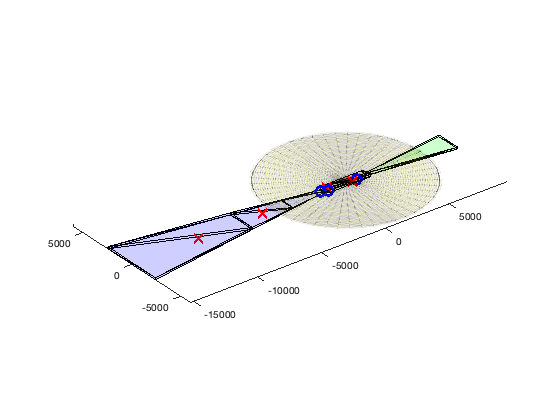



hold on %tener dos O MAS graficas en mismos ejes
plot(Figurapista,'FaceColor','black','FaceAlpha',1); %plot de pista

plot(Figuratrans,'FaceColor','red','FaceAlpha',0.1); %plot de trans
plot(Figuratrans2,'FaceColor','red','FaceAlpha',0.1); %plot de trans2
plot(Figuratrans3,'FaceColor','red','FaceAlpha',0.1); %plot de trans3
plot(Figuratrans4, 'FaceColor','red', 'FaceAlpha',0.1); %plot de trans4
% 
plot(FiguraAprox,'FaceColor','blue','FaceAlpha',0.1); %plot de aprox
plot(FiguraAprox2,'FaceColor','blue','FaceAlpha',0.1); %plot de aprox
plot(FiguraAprox3,'FaceColor','blue','FaceAlpha',0.1); %plot de aprox
% 
plot(FiguraDespegue,'FaceColor','green','FaceAlpha',0.1); %plot de despegue
plot(FiguraCono, 'FaceColor',"yellow", 'FaceAlpha',0.1, "EdgeAlpha",0.05)%plot de cono


hold off